# plot the galaxy and host properties of the JF and non-JF galaxies of he CJF project

## perliminaries


global DEFAULT_MATFILE_DIR
colors=brewermap(9,'Set1');

## load data


% load object table
load([ DEFAULT_MATFILE_DIR '\cosmic_jellyfish_objectTable.mat']);

% load galaxy properties
load([DEFAULT_MATFILE_DIR '\jf_galProperties_CJF.mat']);


## Define JF

threshJF=16;
fprintf('JF Threshold set to %i and above. \n', threshJF);

JF Threshold set to 16 and above. 



maskJF=objectTable.score>=16;
maskNJF=objectTable.score<=5;

% list snaps and redshifts
snaps=unique(objectTable.snap);
zreds=round(10.*illustris.utils.snap2redshift(snaps))./10;

## plot some general info about the sample


nObject=height(objectTable);
fprintf('Total number of objects = %i \n',nObject);

Total number of objects = 37986 


fprintf('Total number of JF = %i (%4.2f %%) \n',sum(maskJF),sum(maskJF)/nObject*100);

Total number of JF = 1571 (4.14 %) 



mask100=objectTable.sim=="TNG100";
mask50=~mask100;
fprintf('TNG100 number of objects = %i (%4.2f %%) \n',sum(mask100),sum(mask100)/nObject*100);

TNG100 number of objects = 24394 (64.22 %) 


fprintf('TNG50 number of objects = %i (%4.2f %%) \n',sum(mask50),sum(mask50)/nObject*100);

TNG50 number of objects = 13592 (35.78 %) 



fprintf('TNG100 number of JFs = %i (%4.2f %%) \n',sum(maskJF & mask100),sum(maskJF & mask100)/sum(mask100)*100);

TNG100 number of JFs = 828 (3.39 %) 


fprintf('TNG50 number of JFs = %i (%4.2f %%) \n',sum(maskJF & mask50),sum(maskJF & mask50)/sum(mask50)*100);

TNG50 number of JFs = 743 (5.47 %) 


## plot stellar mass and host mass functions

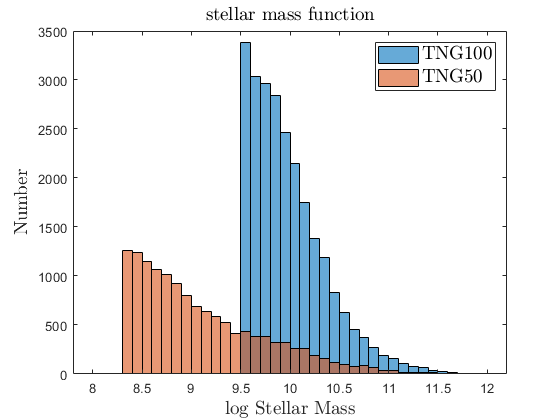

bins=8.0:0.1:12;
figure
histogram(log10(galProps.galStellarMass(mask100)),bins)
hold on
histogram(log10(galProps.galStellarMass(mask50)),bins)
legend(["TNG100","TNG50"],'Interpreter','latex','FontSize',14)
xlabelmine('log Stellar Mass');
ylabelmine('Number');
titlemine('stellar mass function');

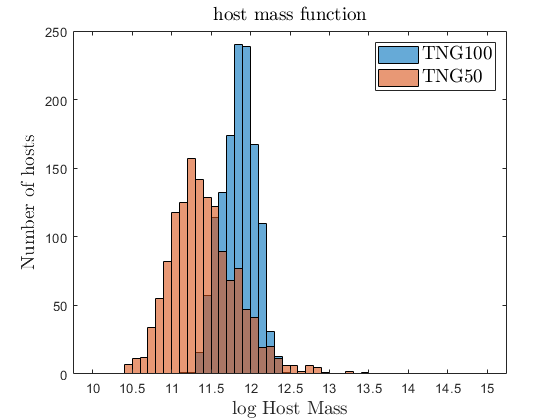


[~,ia,~]=unique(galProps.hostID);
hmass=galProps.hostM200c(ia);
hsim=galProps.sim(ia);

bins=10:0.1:15;
figure
histogram(log10(hmass(hsim=="TNG100")),bins)
hold on
histogram(log10(hmass(hsim=="TNG50")),bins)
legend(["TNG100","TNG50"],'Interpreter','latex','FontSize',14)
xlabelmine('log Host Mass');
ylabelmine('Number of hosts');
titlemine("host mass function");

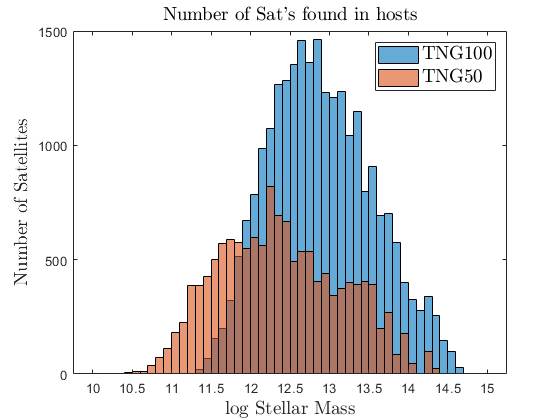



bins=10:0.1:15;
figure
histogram(log10(galProps.hostM200c(mask100)),bins)
hold on
histogram(log10(galProps.hostM200c(mask50)),bins)
legend(["TNG100","TNG50"],'Interpreter','latex','FontSize',14)
xlabelmine('log Stellar Mass');
ylabelmine('Number of Satellites');
titlemine("Number of Sat's found in hosts");

## examine samples by snapshots and simulations

Break down in to simulations and snapshots 

% create table
nums=zeros(length(snaps)+1,3);
jfnums=zeros(length(snaps)+1,3);
for i=1:length(snaps)
    snpMask=objectTable.snap==snaps(i);
    
    nums(i,1)=sum(snpMask);
    nums(i,2)=sum(snpMask & mask50);
    nums(i,3)=sum(snpMask & mask100);
    
    jfnums(i,1)=sum(snpMask & maskJF);
    jfnums(i,2)=sum(snpMask & mask50 & maskJF);
    jfnums(i,3)=sum(snpMask & mask100 & maskJF);
    
end
nums(end,:)=sum(nums(1:end-1,:),1);
jfnums(end,:)=sum(jfnums(1:end-1,:),1);

zr=string(num2str(zreds'));
zr(end+1)=" ";

Table of objects for each snapshot and simulaiton

numTab=table(zr,nums(:,1),nums(:,1)./nums(end,1).*100,...
    nums(:,2),nums(:,2)./nums(end,2).*100,...
    nums(:,3),nums(:,3)./nums(end,3).*100,...
    'variableNames',{'redshift','total','total % ','TNG50','TNG50 %','TNG100','TNG100 %'}, ...
    'RowNames',[string(num2str(snaps)); "total"]);
head(numTab,11)

ans = 11×7 table
             redshift    total    total %     TNG50    TNG50 %    TNG100    TNG100 %
             ________    _____    ________    _____    _______    ______    ________

    33        "  2"       2234     5.8811       949     6.982      1285      5.2677 
    40        "1.5"       3173     8.3531      1223    8.9979      1950      7.9938 
    50        "  1"       3876     10.204      1391    10.234      2485      10.187 
    59        "0.7"       4225     11.123      1458    10.727      2767      11.343 
    67        "0.5"       4216     11.099      1462    10.756      2754       11.29 
    72        "0.4"       4276     11.257      

Table of JFs in each snap and simulation - also with JF fractions (in percent)  - JF over all objects in each snap/sim 

jfTab=table(zr,jfnums(:,1),jfnums(:,1)./jfnums(end,1).*100,jfnums(:,1)./nums(:,1).*100,...
    jfnums(:,2),jfnums(:,2)./jfnums(end,2).*100,jfnums(:,2)./nums(:,2).*100,...
    jfnums(:,3),jfnums(:,3)./jfnums(end,3).*100,jfnums(:,3)./nums(:,3).*100,...
    'variableNames',{'redshift','total','total %','total jf_frac',...
    'TNG50','TNG50 %','TNG50 jf_frac',...
    'TNG100','TNG100 %','TNG100 jf_frac'}, ...
    'RowNames',[string(num2str(snaps)); "total"]);
head(jfTab,11)

ans = 11×10 table
             redshift    total    total %    total jf_frac    TNG50    TNG50 %    TNG50 jf_frac    TNG100    TNG100 %    TNG100 jf_frac
             ________    _____    _______    _____________    _____    _______    _____________    ______    ________    ______________

    33        "  2"        11     0.70019       0.49239          8     1.0767        0.84299          3      0.36232        0.23346    
    40        "1.5"        32      2.0369        1.0085         20     2.6918         1.6353         12       1.4493        0.61538    
    50        "  1"       100      6.3654     


% create object table
% objectTable=table(idList,clsTab.snap(ia),clsTab.subfind(ia),clsTab.host(ia),...
%     'variableNames',{'subject_ids','snap','subfind','host'});

## plot JF numbers  and  fractions as a function of redshift

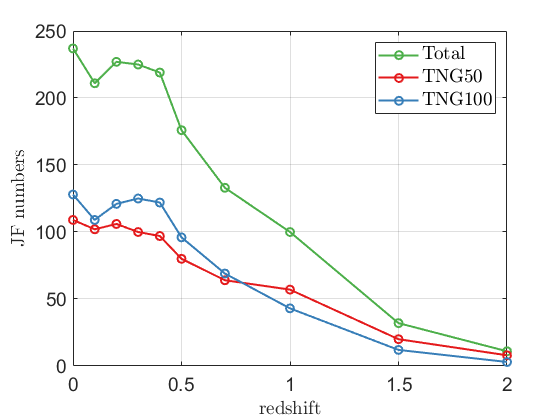

h=[];
figure
h(end+1)=plot(zreds,jfTab.("total")(1:end-1),'-o','color',colors(3,:),'linewidth',1.5,...
    'DisplayName','Total');
hold on
h(end+1)=plot(zreds,jfTab.("TNG50")(1:end-1),'-o','color',colors(1,:),'linewidth',1.5,...
    'DisplayName','TNG50');
h(end+1)=plot(zreds,jfTab.("TNG100")(1:end-1),'-o','color',colors(2,:),'linewidth',1.5,...
    'DisplayName','TNG100');

grid
set(gca,'FontSize',14)
legend(h,'Interpreter',"latex",'location','northeast','fontsize',14);
xlabelmine('redshift');
ylabelmine('JF numbers');

There are similar number of JF galaxies in the two simulations, despite the differences in the total numbers (this will be more prominent in the JF fractions). Numbers of JF increase with time / decreasing redshift

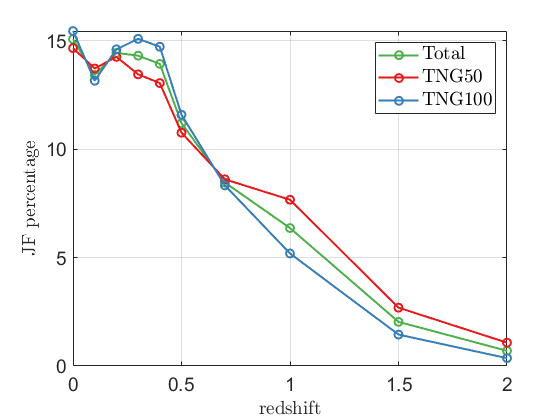


h=[];
figure
h(end+1)=plot(zreds,jfTab.("total %")(1:end-1),'-o','color',colors(3,:),'linewidth',1.5,...
    'DisplayName','Total');
hold on
h(end+1)=plot(zreds,jfTab.("TNG50 %")(1:end-1),'-o','color',colors(1,:),'linewidth',1.5,...
    'DisplayName','TNG50');
h(end+1)=plot(zreds,jfTab.("TNG100 %")(1:end-1),'-o','color',colors(2,:),'linewidth',1.5,...
    'DisplayName','TNG100');

grid
set(gca,'FontSize',14)
legend(h,'Interpreter',"latex",'location','northeast','fontsize',14);
xlabelmine('redshift');
ylabelmine('JF percentage');

Out of all JF galaxies in the sample, the breakdown into snapshots is similar in the two simulations. 

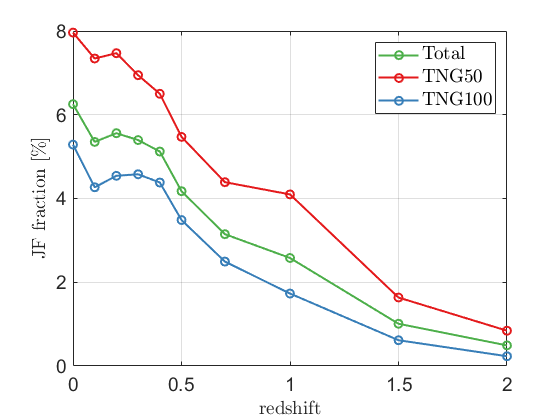


h=[];
figure
h(end+1)=plot(zreds,jfTab.("total jf_frac")(1:end-1),'-o','color',colors(3,:),'linewidth',1.5,...
    'DisplayName','Total');
hold on
h(end+1)=plot(zreds,jfTab.("TNG50 jf_frac")(1:end-1),'-o','color',colors(1,:),'linewidth',1.5,...
    'DisplayName','TNG50');
h(end+1)=plot(zreds,jfTab.("TNG100 jf_frac")(1:end-1),'-o','color',colors(2,:),'linewidth',1.5,...
    'DisplayName','TNG100');

grid
set(gca,'FontSize',14)
legend(h,'Interpreter',"latex",'location','northeast','fontsize',14);
xlabelmine('redshift');
ylabelmine('JF fraction [\%]');

We find a higher JF fraction in TNG50 than in TNG100 - This could be due to several reasons

- the higher resolution leads to more JF, or better resolved JF

- There are more JF in lower stellar masses - TNG50 has higher porportion of low-mass galaxies so the JF fraction increases

- Is the TNG50 sample dominated by sat's in high-mass hosts? that could also lead to an increase. 

## Demographics 

We show some demographics of the JF population in terms of galaxy mass, host mass and galaxy to host ratio .

% perliminaries
for i=1:length(zreds)
    zredLab{i}=sprintf('z=%s',num2str(zreds(i),'%3.1f'));
end
global DEFAULT_PRINTOUT_DIR
outputDir=[ DEFAULT_PRINTOUT_DIR '/jellyfish'];

outputDir = 'C:\Users\eladz\Documents\workProjects/IllustrisTNG/printout/jellyfish'


missingColor=0.95.*[1 1 1];

## JF fractions  vs. stellar mass for each sim and snapshot

% build data matrix
msBins=8:0.5:12;
binIndx=discretize(log10(galProps.galStellarMass),msBins);


galNum=zeros(length(zreds),length(msBins)-1,2);
%galNum100=zeros(length(zreds),length(msBins)-1);
cdata=galNum;
for i=1:length(zreds)
    snapMask100=galProps.snap==snaps(i) & galProps.sim=='TNG100';
    snapMask50=galProps.snap==snaps(i) & galProps.sim=='TNG50';
    for j=1:length(msBins)-1
        msMask=binIndx==j;
        galNum(i,j,1)=sum(snapMask50 & msMask');
        galNum(i,j,2)=sum(snapMask100 & msMask');
        
        
        cdata(i,j,1)=sum(snapMask50 & msMask' & maskJF);
        cdata(i,j,2)=sum(snapMask100 & msMask' & maskJF);
    end
end

%cdata=cdata(:,:,1),./sum(sum(cdata)).*100;
cdata=cdata./galNum.*100;


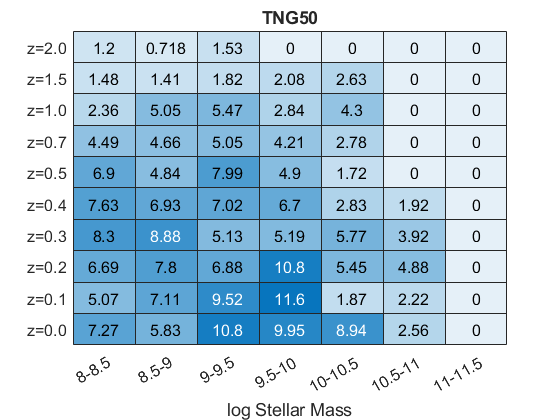


msLab={};
 for i=1:2:length(msBins)-1
%     msLab{i}=sprintf('%s-%s',num2str(msBins(i),'%3.1f'),...
%         num2str(msBins(i+1),'%3.1f'));
ss=num2str(floor(msBins(i)),'%i');
sss=num2str(floor(msBins(i+2)),'%i');
    msLab{i}=[ss '-' ss '.5'];
    msLab{i+1}=[ss '.5' '-' sss];
    
 end


% TNG50
spn=1:length(msLab)-1;
cd=squeeze(cdata(:,spn,1));
%cd=squeeze(cdata(:,spn,1));
figure
ht=heatmap(msLab(spn),zredLab,cd,'MissingDataColor',missingColor);
caxis([0 ceil(max(max(cd)))])
colorbar('off')
ht.xlabel('log Stellar Mass')
%ht.ylabel('Redshift')
ht.FontSize=12;
ht.CellLabelFormat = '%.3g';
ht.title('TNG50')
printout_fig(gcf,'jfDemograf_stellarMass_TNG50','dir',outputDir)

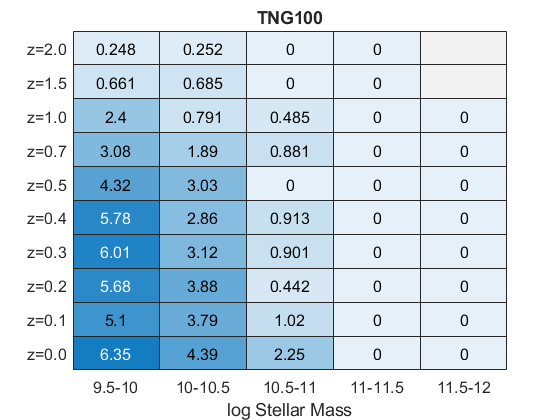



spn=4:length(msLab);
cd=squeeze(cdata(:,spn,2));
figure
ht=heatmap(msLab(spn),zredLab,cd,'MissingDataColor',missingColor);
caxis([0 ceil(max(max(cd)))])
colorbar('off')
ht.xlabel('log Stellar Mass')
%ht.ylabel('Redshift')
ht.FontSize=12;
ht.CellLabelFormat = '%.3g';
ht.title('TNG100')
printout_fig(gcf,'jfDemograf_stellarMass_TNG100','dir',outputDir)

## JF fractions vs. halo mass

% build data matrix
msBins=10:0.5:15;
binIndx=discretize(log10(galProps.hostM200c),msBins);


galNum=zeros(length(zreds),length(msBins)-1,2);
%galNum100=zeros(length(zreds),length(msBins)-1);
cdata=galNum;
for i=1:length(zreds)
    snapMask100=galProps.snap==snaps(i) & galProps.sim=='TNG100';
    snapMask50=galProps.snap==snaps(i) & galProps.sim=='TNG50';
    for j=1:length(msBins)-1
        msMask=binIndx==j;
        galNum(i,j,1)=sum(snapMask50 & msMask');
        galNum(i,j,2)=sum(snapMask100 & msMask');
        
        cdata(i,j,1)=sum(snapMask50 & msMask' & maskJF);
        cdata(i,j,2)=sum(snapMask100 & msMask' & maskJF);
    end
end

%cdata=cdata(:,:,1),./sum(sum(cdata)).*100;
cdata=cdata./galNum.*100;


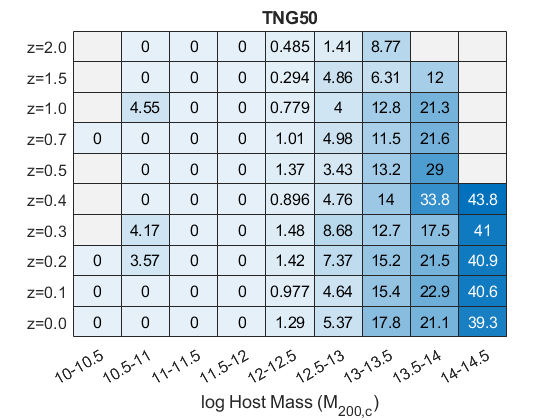

msLab={};
 for i=1:2:length(msBins)-1
%     msLab{i}=sprintf('%s-%s',num2str(msBins(i),'%3.1f'),...
%         num2str(msBins(i+1),'%3.1f'));
ss=num2str(floor(msBins(i)),'%i');
sss=num2str(floor(msBins(i+2)),'%i');
    msLab{i}=[ss '-' ss '.5'];
    msLab{i+1}=[ss '.5' '-' sss];
    
 end


% TNG50
spn=1:length(msLab)-1;
cd=squeeze(cdata(:,spn,1));
figure
ht=heatmap(msLab(spn),zredLab,cd,'MissingDataColor',missingColor);
caxis([0 ceil(max(max(cd)))])
colorbar('off')
ht.xlabel('log Host Mass (M_{200,c})')
%ht.ylabel('Redshift')
ht.FontSize=12;
ht.CellLabelFormat = '%.3g';
ht.title('TNG50')
printout_fig(gcf,'jfDemograf_hostMass_TNG50','dir',outputDir)

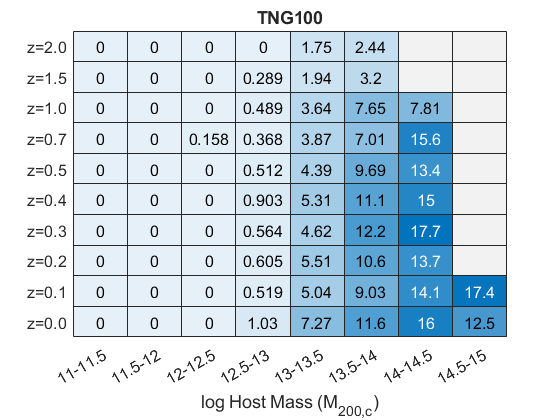


spn=3:length(msLab);
cd=squeeze(cdata(:,spn,2));
figure
ht=heatmap(msLab(spn),zredLab,cd,'MissingDataColor',missingColor);
caxis([0 ceil(max(max(cd)))])
colorbar('off')
ht.xlabel('log Host Mass (M_{200,c})')
%ht.ylabel('Redshift')
ht.FontSize=12;
ht.CellLabelFormat = '%.3g';
ht.title('TNG100')
printout_fig(gcf,'jfDemograf_hostMass_TNG100','dir',outputDir)

## JF fractions vs. sat-halo mass fraction 

% build data matrix
massRat=galProps.galStellarMass./galProps.hostM200c;
msBins=-6:0.5:-1;
binIndx=discretize(log10(massRat),msBins);


galNum=zeros(length(zreds),length(msBins)-1,2);
%galNum100=zeros(length(zreds),length(msBins)-1);
cdata=galNum;
for i=1:length(zreds)
    snapMask100=galProps.snap==snaps(i) & galProps.sim=='TNG100';
    snapMask50=galProps.snap==snaps(i) & galProps.sim=='TNG50';
    for j=1:length(msBins)-1
        msMask=binIndx==j;
        galNum(i,j,1)=sum(snapMask50 & msMask');
        galNum(i,j,2)=sum(snapMask100 & msMask');
        
        cdata(i,j,1)=sum(snapMask50 & msMask' & maskJF);
        cdata(i,j,2)=sum(snapMask100 & msMask' & maskJF);
        
    end
end

%cdata=cdata(:,:,1),./sum(sum(cdata)).*100;
cdata=cdata./galNum.*100;


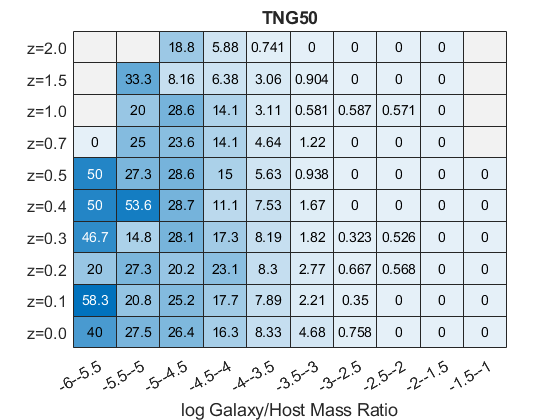

msLab={};
 for i=1:2:length(msBins)-1
%     msLab{i}=sprintf('%s-%s',num2str(msBins(i),'%3.1f'),...
%         num2str(msBins(i+1),'%3.1f'));
ss=num2str(floor(msBins(i)),'%i');
sss=num2str(floor(msBins(i+2)),'%i');
    msLab{i}=[ss '-' sss '.5'];
    msLab{i+1}=[sss '.5' '-' sss];
    
 end


% TNG50
spn=1:length(msLab);
cd=squeeze(cdata(:,spn,1));
figure
ht=heatmap(msLab(spn),zredLab,cd,'MissingDataColor',missingColor);
caxis([0 ceil(max(max(cd)))])
colorbar('off')
ht.xlabel('log Galaxy/Host Mass Ratio')
%ht.ylabel('Redshift')
ht.FontSize=12;
ht.CellLabelFormat = '%.3g';
ht.title('TNG50')
printout_fig(gcf,'jfDemograf_massRatio_TNG50','dir',outputDir)

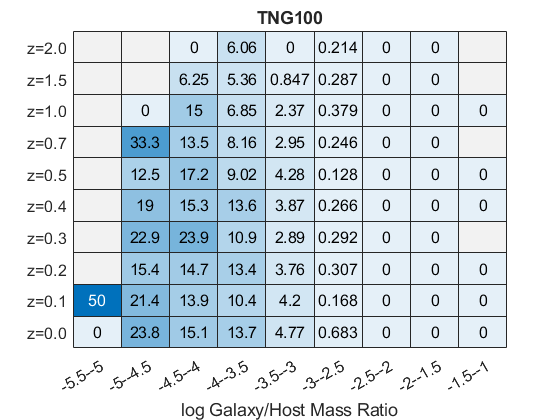


spn=2:length(msLab);
cd=squeeze(cdata(:,spn,2));
figure
ht=heatmap(msLab(spn),zredLab,cd,'MissingDataColor',missingColor);
caxis([0 ceil(max(max(cd)))])
colorbar('off')
ht.xlabel('log Galaxy/Host Mass Ratio')
%ht.ylabel('Redshift')
ht.FontSize=12;
ht.CellLabelFormat = '%.3g';
ht.title('TNG100')
printout_fig(gcf,'jfDemograf_massRatio_TNG100','dir',outputDir)

## JF and gal properties



% zz=illustris.utils.snap2redshift(objectTable.snap');
% dataMat=cat(1,log10(galProps.galStellarMass),log10(galProps.hostM200c),log10(galProps.galSFR+1e-5),zz)';
%
% labs={'stellar','host','SFR','gz'};
% score=zeros(size(maskJF));
% score(maskNJF)=0;
% score(maskJF)=2;
% score(~maskJF & ~maskNJF)=1;
% %score(score<5)=0;
%
% %cc=brewermap(8,'Accent');
%
% gplotmatrix(dataMat,[],score,colors([1 3 2],:),'o+',[1.5,5],...
% 'on',[],labs,labs)
% titlemine('All');
% %printout_fig(gcf,'jf_perlim_scores56')
%
% % TNG100
% dataMat=cat(1,log10(galProps.galStellarMass(mask100)),log10(galProps.hostM200c(mask100)),log10(galProps.galSFR(mask100)+1e-5),zz(mask100))';
%
% labs={'stellar','host','SFR','z'};
% score=maskJF(mask100);
% %score(score<5)=0;
%
% %cc=brewermap(8,'Accent');
%
% gplotmatrix(dataMat,[],score,colors([1 2],:),'o+',[1.5,5],...
% 'on',[],labs,labs)
% titlemine('TNG100');
%
% %TNG50
% dataMat=cat(1,log10(galProps.galStellarMass(mask50)),log10(galProps.hostM200c(mask50)),log10(galProps.galSFR(mask50)+1e-5),zz(mask50))';
%
% labs={'stellar','host','SFR','z'};
% score=maskJF(mask50);
% %score(score<5)=0;
%
% %cc=brewermap(8,'Accent');
%
% gplotmatrix(dataMat,[],score,colors([1 2],:),'o+',[1.5,5],...
% 'on',[],labs,labs)
% titlemine('TNG50');

%
%
%     dataMat=cat(1,log10(galProps.galStellarMass),log10(galProps.hostM200c),...
%         log10(galProps.galGasMass),log10(galProps.galSFR+1e-5))';
%     labs={'stellar','host','gas','SFR'};
%     score=tall;
%     score(score<5)=0;
%     score(score>=5)=1;
%     cc=brewermap(8,'Accent');
%     %% try out figure for scores 5 and 6
%     figure;
%     gplotmatrix(dataMat,[],score,cc([6 5],:),'s+',[1.5,5],...
%         'on',[],labs,labs)
%     titlemine('All Redshifts');
%
%

%
%
% for i=1:length(snaps)
%     inds=objectTable.snap==snaps(i);
%     dataMat=cat(1,log10(galProps.galStellarMass(inds)),log10(galProps.hostM200c(inds)),...
%         log10(galProps.galGasMass(inds)),log10(galProps.galSFR(inds)+1e-5))';
%     labs={'stellar','host','gas','SFR'};
%     score=tally6(inds);
%     score(score<5)=0;
%     score(score>=5)=1;
%     cc=brewermap(8,'Accent');
%     %% try out figure for scores 5 and 6
%     figure;
%     gplotmatrix(dataMat,[],score,cc([6 5],:),'s+',[1.5,5],...
%         'on',[],labs,labs)
%     titlemine(['$z=' num2str(zreds(i)) '$']);
% end
%
%